A = [0 1 ; -25 -4];
B = [1 1 ; 0 1];
C = [1 0 ; 0 1];
D = [0 0 ; 0 0];

sys = ss(A, B, C, D);
Gp = tf(sys)


Gp =
 
  From input 1 to output...
           s + 4
   1:  --------------
       s^2 + 4 s + 25
 
            -25
   2:  --------------
       s^2 + 4 s + 25
 
  From input 2 to output...
           s + 5
   1:  --------------
       s^2 + 4 s + 25
 
           s - 25
   2:  --------------
       s^2 + 4 s + 25
 
Continuous-time transfer function.


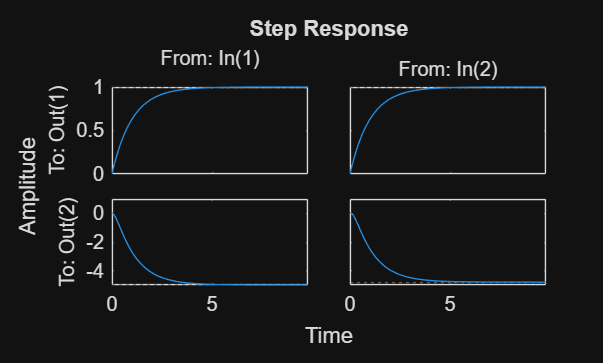

Gf = feedback(Gp,eye(2));

step(Gf)

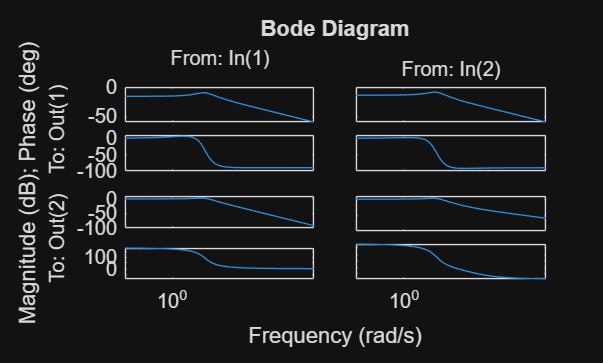

bode(Gp)

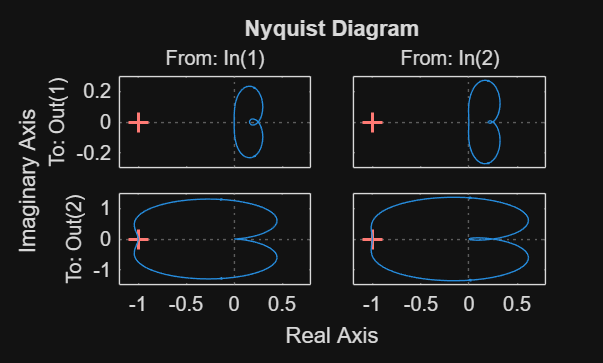

nyquist(Gp)